# Lektion 9 - Problems 8.14, Random Signals p. 553

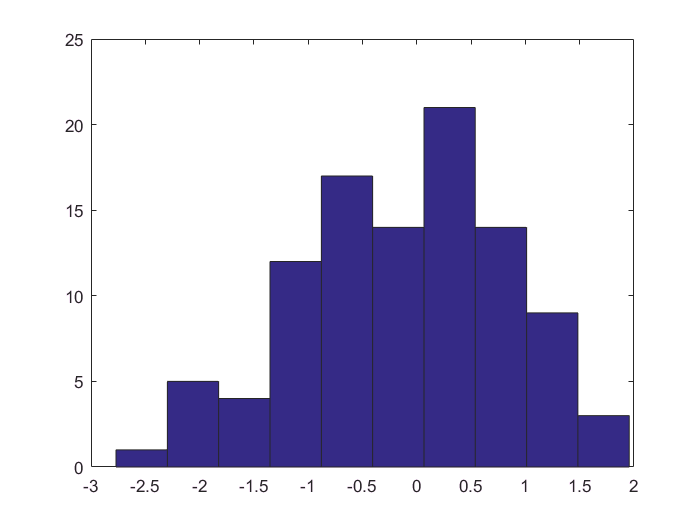

X = randn(1,100);

hist(X);

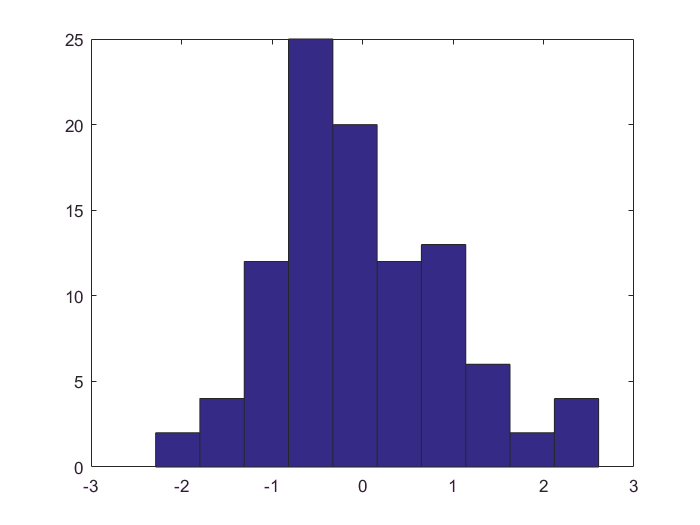


Y = randn(1,100);

hist(Y)

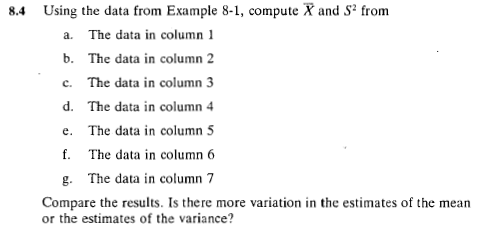

a = [3.42 3.48 3.54 3.51 3.48 3.57 3.59 3.63 3.50 3.45 3.51 3.55 3.59 3.50 3.61];

a_mean = sum(a)/length(a)

a_mean = 3.5287

a_mean = mean(a)

a_mean = 3.5287


a_var = 1/(length(a)-1).*sum((a-a_mean).^2)

a_var = 0.0037

a_var = var(a) 

a_var = 0.0037

# Lecture Notes on Statistics Problems: Chap.1: 1-4

1. In the cup filling example, suppose we had observed a sample mean of ${\mu^{ˆ} }_{\text{obs}} =260g$� grams.

Would you then conclude that the machine is adequately calibrated or not? You need to redo the hypothesis test to answer this question. A p-value smaller than 0.05 suggests that the machine is not adequately calibrated. Explain in words why that is.

Rather than expressing the hypothesis in terms of the samples, it is more convenient to express it in terms of a test statistic.

mu_obs = 260; mu = 250; sigma = 2.5; n = 25;

z = (mu_obs-mu)/((sigma)/sqrt(n))

z = 20

p = 1-normcdf(z)

p = 0

We reject the hypothesis since the p-value ($p=0$) is smaller than 0.05. 

If the machine was adequately calibrated, it would be unlikely to observe a sample mean that is more extreme than 260 grams. The machine is not adequately calibrated.

2. What range of values of ${\mu^{ˆ} }_{\text{obs}}$ would give rise to a p-value larger than 0.05? (i.e., what is the range of sample mean values for which we would conclude that the machine is adequately calibrated.).

Note that because of the way we interpret the p-value, it only makes sense to consider �${\mu^{ˆ} }_{\text{obs}} \ge \mu =250$.

Calculates the p-value for ${\mu^{ˆ} }_{\text{obs}}$ ranging from 250 to 250 at intervals of 0.1. By plotting the p-value against ${\mu^{ˆ} }_{\text{obs}}$ I can find out where the p-value is 0.05.

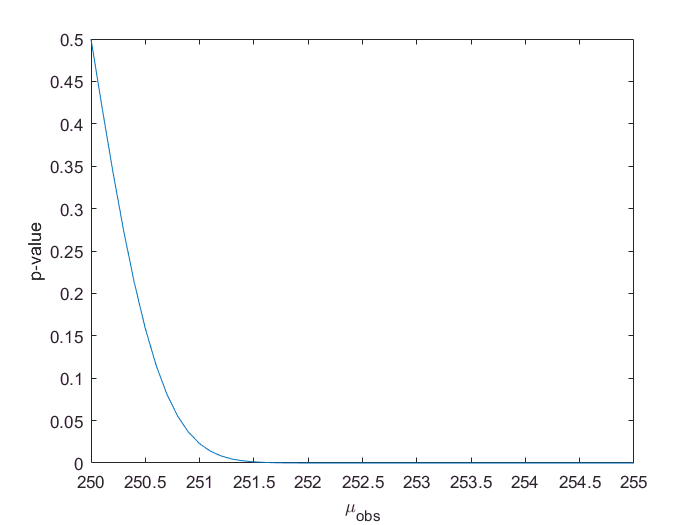

range=250:0.1:255;
pval=1-normcdf((range-250)/(2.5/sqrt(25)));
plot(range,pval)
xlabel('\mu_{obs}')
ylabel('p-value')


p = pval(9)

p = 0.0548

mu_obs = range(9)

mu_obs = 250.8000

3. It is common to look at the absolute value of the deviation from the true mean, $|{\mu −\mu^{ˆ} }_{\text{obs}} |$.

 In the example above this implies that we would not distinguish between${\mu^{ˆ} }_{\text{obs}} =250\ldotp 2g$  and ${\mu^{ˆ} }_{\text{obs}} =249\ldotp 8g$, because they would both give rise to a deviation from the mean with an absolute value of 0.2. In this case, the p-value is

This is called a two-sided p-value (as opposed to the above definition, which is a one-sided pvalue). Calculate the two-sided p-value when${\mu^{ˆ} }_{\text{obs}} =250\ldotp 2g$.

mu_obs1 = 250.2; mu_obs2 = 249.8; mu = 250; sigma = 2.5; n = 25;

z1 = (mu_obs1-mu)/((sigma)/sqrt(n))

z1 = 0.4000

p1 = 1-normcdf(z1)

p1 = 0.3446


z2 = (mu_obs2-mu)/((sigma)/sqrt(n))

z2 = -0.4000

p2 = normcdf(z2)

p2 = 0.3446


p = p1+p2

p = 0.6892

The p-value is 0.34 + 0.34 = 0.68 (there is a 68% chance of observing a sample mean that is more extreme than 250.2 g). 

The machine is adequately calibrated.

4. Using the two-sided p-value, as defined in Problem 3, what range of values of ${\mu^{ˆ} }_{\text{obs}}$ would give rise to a p-value larger than 0.05?

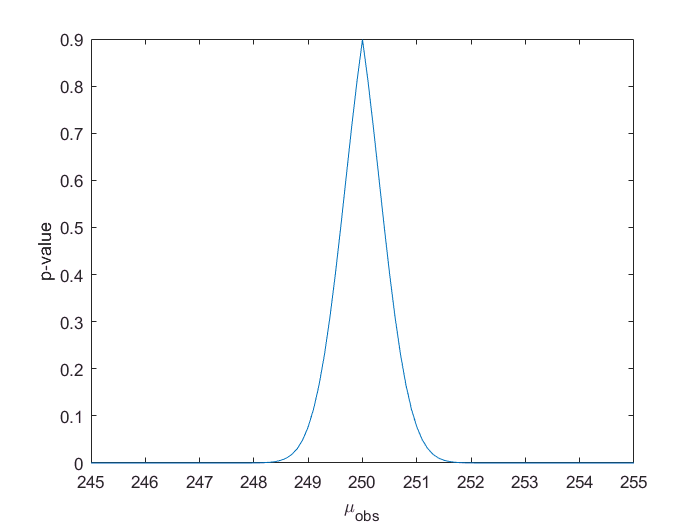

range=245:0.1:255;
z = (range-250)/(2.5/sqrt(25));
pval = 1-normcdf(abs(z)) + normpdf(abs(z));
plot(range,pval)
xlabel('\mu_{obs}')
ylabel('p-value')


p1 = pval(40)

p1 = 0.0494

mu_obs1 = range(40)

mu_obs1 = 248.9000


p2 = pval(66)

p2 = 0.0058

mu_obs2 = range(66)

mu_obs2 = 251.5000